# Lab 6: Sensor Modeling

% data
trial1 = [1,0.0,18.0,3.21289
2,0.108002,18.0,3.22266
3,0.214996,18.0,3.21777
4,0.322998,18.0,3.22266
5,0.429993,18.0,3.22266
6,0.537994,18.0,3.21777
7,0.644989,18.0,3.22266
8,0.752991,18.0,3.22266
9,0.860992,18.0,3.22754
10,0.967987,18.0,3.21777
11,1.077,18.0,3.21289
12,1.18399,18.0,3.22266
13,1.29199,18.0,3.20801
14,1.39899,18.0,3.22266
15,1.50601,18.0,3.21777
16,1.61401,18.0,3.22266
17,1.72101,18.0,3.22266
18,1.82901,18.0,3.23242
19,1.936,18.0,3.22266
20,2.04401,18.0,3.22266
21,2.151,18.0,3.22266
22,2.258,18.0,3.21777
23,2.366,18.0,3.21289
24,2.47299,18.0,3.21777
25,2.58099,18.0,3.21289
26,2.68799,18.0,3.21289
27,2.79599,18.0,3.19824
28,2.90399,18.0,3.21289
29,3.01099,18.0,3.22266
30,3.11899,18.0,3.21777
31,3.22601,18.0,3.21289
32,3.33401,18.0,3.22266
33,3.44101,18.0,3.20313
34,3.548,18.0,3.22266
35,3.65601,18.0,3.21777
36,3.763,18.0,3.22266
37,3.871,18.0,3.21777
38,3.978,18.0,3.22266
39,4.086,18.0,3.20313
40,4.19299,18.0,3.21777
41,4.29999,18.0,3.22266
42,4.40799,18.0,3.21777
43,4.51501,18.0,3.22754
44,4.62302,18.0,3.24219
45,4.73099,18.0,3.21777
46,4.83801,18.0,3.21289
47,4.94601,18.0,3.21777
48,5.05301,18.0,3.21289
49,5.16101,18.0,3.22266
50,5.26801,18.0,3.20313];

trial2 = [1,0.0,14.0,2.52441
2,0.108032,14.0,2.50977
3,0.215027,14.0,2.52441
4,0.323059,14.0,2.5293
5,0.430054,14.0,2.52441
6,0.538025,14.0,2.51465
7,0.64502,14.0,2.5293
8,0.752014,14.0,2.51953
9,0.860046,14.0,2.50977
10,0.968018,14.0,2.5
11,1.07501,14.0,2.57813
12,1.18201,14.0,2.59766
13,1.29004,14.0,2.50977
14,1.39703,14.0,2.52441
15,1.505,14.0,2.57324
16,1.61304,14.0,2.53418
17,1.72003,14.0,2.5
18,1.828,14.0,2.50977
19,1.93402,14.0,2.52441
20,2.04102,14.0,2.53418
21,2.14801,14.0,2.63672
22,2.255,14.0,2.51465
23,2.36304,14.0,2.51465
24,2.47003,14.0,2.51465
25,2.578,14.0,2.51465
26,2.68506,14.0,2.50977
27,2.79205,14.0,2.5
28,2.90002,14.0,2.50488
29,3.00702,14.0,2.51465
30,3.11505,14.0,2.50488
31,3.22205,14.0,2.50488
32,3.33002,14.0,2.50977
33,3.43701,14.0,2.50488
34,3.54401,14.0,2.51953
35,3.65204,14.0,2.5
36,3.75903,14.0,2.5
37,3.867,14.0,2.50488
38,3.97406,14.0,2.5
39,4.08203,14.0,2.5
40,4.18903,14.0,2.5
41,4.29602,14.0,2.5
42,4.40405,14.0,2.49512
43,4.51105,14.0,2.49512
44,4.61902,14.0,2.49023
45,4.72601,14.0,2.48535
46,4.83301,14.0,2.48535
47,4.94104,14.0,2.49512
48,5.04803,14.0,2.51465
49,5.15601,14.0,2.49512
50,5.263,14.0,2.48047];

trial3 = [1,0.000976563,8.5,1.61621
2,0.107971,8.5,1.60156
3,0.214966,8.5,1.60645
4,0.322998,8.5,1.61621
5,0.429993,8.5,1.61133
6,0.537964,8.5,1.60645
7,0.645996,8.5,1.60645
8,0.752991,8.5,1.60645
9,0.859985,8.5,1.59668
10,0.967957,8.5,1.60645
11,1.07599,8.5,1.62598
12,1.18298,8.5,1.62109
13,1.29095,8.5,1.68945
14,1.39795,8.5,1.60156
15,1.505,8.5,1.60156
16,1.61298,8.5,1.61133
17,1.71997,8.5,1.63086
18,1.828,8.5,1.61133
19,1.935,8.5,1.60156
20,2.04199,8.5,1.59668
21,2.14996,8.5,1.59668
22,2.25696,8.5,1.5918
23,2.36499,8.5,1.60645
24,2.47198,8.5,1.60156
25,2.57996,8.5,1.60645
26,2.68695,8.5,1.61621
27,2.79401,8.5,1.59668
28,2.90198,8.5,1.5918
29,3.00897,8.5,1.60156
30,3.117,8.5,1.63574
31,3.224,8.5,1.60645
32,3.33197,8.5,1.61621
33,3.43896,8.5,1.5918
34,3.54596,8.5,1.60156
35,3.65399,8.5,1.59668
36,3.76099,8.5,1.58691
37,3.86896,8.5,1.58203
38,3.97595,8.5,1.58691
39,4.08295,8.5,1.5918
40,4.19098,8.5,1.60645
41,4.29797,8.5,1.60156
42,4.40601,8.5,1.61133
43,4.513,8.5,1.61621
44,4.62097,8.5,1.60156
45,4.72797,8.5,1.60156
46,4.83496,8.5,1.59668
47,4.94299,8.5,1.59668
48,5.04999,8.5,1.58691
49,5.15796,8.5,1.58203
50,5.26495,8.5,1.60156];

trial4 = [1,0.0,2.0,0.639648
2,0.10791,2.0,0.629883
3,0.214966,2.0,0.634766
4,0.322998,2.0,0.634766
5,0.429932,2.0,0.634766
6,0.536987,2.0,0.654297
7,0.644897,2.0,0.654297
8,0.75293,2.0,0.649414
9,0.859985,2.0,0.654297
10,0.966919,2.0,0.65918
11,1.07397,2.0,0.673828
12,1.18188,2.0,0.65918
13,1.28894,2.0,0.65918
14,1.39697,2.0,0.649414
15,1.50391,2.0,0.639648
16,1.61194,2.0,0.65918
17,1.71899,2.0,0.654297
18,1.82593,2.0,0.65918
19,1.93396,2.0,0.654297
20,2.04089,2.0,0.654297
21,2.14893,2.0,0.644531
22,2.25696,2.0,0.654297
23,2.36499,2.0,0.639648
24,2.47192,2.0,0.644531
25,2.57898,2.0,0.644531
26,2.68591,2.0,0.649414
27,2.79297,2.0,0.673828
28,2.901,2.0,0.664063
29,3.00793,2.0,0.65918
30,3.11499,2.0,0.649414
31,3.2229,2.0,0.664063
32,3.32996,2.0,0.644531
33,3.43799,2.0,0.639648
34,3.54492,2.0,0.649414
35,3.65295,2.0,0.654297
36,3.76099,2.0,0.644531
37,3.86792,2.0,0.664063
38,3.97595,2.0,0.654297
39,4.08289,2.0,0.65918
40,4.19092,2.0,0.673828
41,4.29797,2.0,0.664063
42,4.40588,2.0,0.649414
43,4.51294,2.0,0.654297
44,4.6189,2.0,0.683594
45,4.72693,2.0,0.668945
46,4.83398,2.0,0.654297
47,4.94189,2.0,0.65918
48,5.04895,2.0,0.65918
49,5.15588,2.0,0.654297
50,5.26392,2.0,0.65918];

% concatenate data and polyfit
height = [trial1(:,3); trial2(:,3); trial3(:,3); trial4(:,3)];
volts = [trial1(:,4); trial2(:,4); trial3(:,4); trial4(:,4)];
[p,S] = polyfit(height,volts,1);
[y_fit,delta] = polyval(p,height,S);

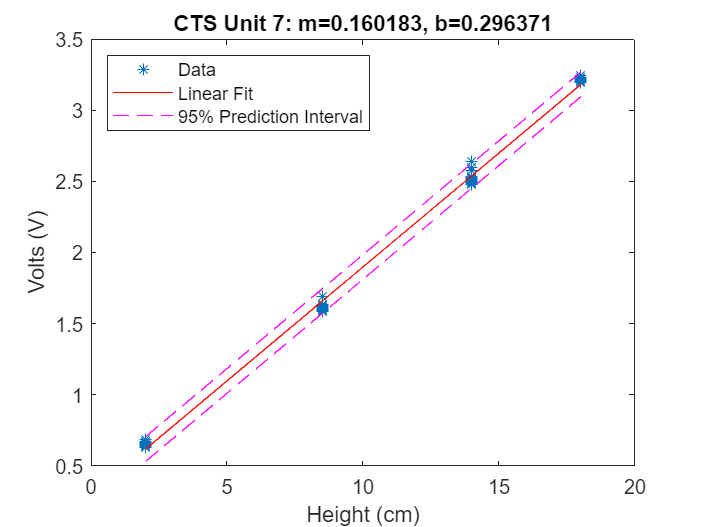

% plot data
plot(height,volts,'*')
hold on
plot(height,y_fit,'r')
plot(height,y_fit+2*delta,'m--',height,y_fit-2*delta,'m--')
hold off
title(sprintf("CTS Unit 7: m=%f, b=%f", p(1), p(2)))
xlabel("Height (cm)")
ylabel("Volts (V)")
legend('Data','Linear Fit','95% Prediction Interval', 'Location', 'northwest')